## **V-n diagram**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0 Design Parameters**

**0.1 Sea Level**

[T0, a0, P0, rho0] = atmosisa(0);  % Sea Level Condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

**0.2 Aircraft Design Parameters**

weight

W0 = 4.2990e+05;                   % Maximum take-off gross weight (kg)
W0 = W0 * g;                       % Maximum take-off gross weight (N)
WC = 0.9554 .* W0;                 % Cruise weight when starting 1st cruise (N)
% WC = 0.5806 .* W0;               % Cruise weight when ending 1st cruise (N)
WL = 0.9 .* W0;                    % Landing design gross weight (N)

wing

a = 4.4359;                        % Wing lift curve slope at clean configuration (1/rad)

CLmax = 1.4413;                    % Maximum lift coefficient at clean configuration
CLmaxTO = 2.2290;                  % Maximum lift coefficient at takeoff configuration
CLmaxL = 2.8734;                   % Maximum lift coefficient at landing configuration
CLmaxA = 2.5154;                   % Maximum lift coefficient at approach configuration
CD0 = 0.0188;                      % Drag coefficient at zero lift

b = 65;                            % Wing span (m)
Sref = 548.7;                      % Reference wing area (m^2)
c = Sref ./ b;                     % Mean geometric chord of the wing (m)
Sweep = 25.5257;                   % Wing 1/4 chord sweep (degree)
Sweep = deg2rad(Sweep);            % Wing 1/4 chord sweep (rad)

### **1 Design Airspeeds (Part I)**

The selected design airspeeds are equivalent airspeeds (EAS)

**1.1 Design Cruising Speed, **$V_C$

CS 25.335 (a) (p.212)

Airframe Structural Design (p.76)

MC = 0.83;                         % Design cruising speed (Mach)

C_alt = 28000;                     % Design cruising altitude (ft)
Calt = convlength(C_alt, 'ft','m') % Design cruising altitude (m)

Calt = 8.5344e+03


[TC, aC, PC, rhoC] = atmosisa(Calt);


$$V_{\textrm{EAS}} =\sqrt{\frac{\rho }{\rho_0 }}V_{\textrm{TAS}}$$


VC_TAS = aC .* MC                  % Design cruising true airspeed (m/s)

VC_TAS = 253.8045

VC = sqrt(rhoC ./ rho0) .* VC_TAS  % Design cruising equivalent airspeed (m/s)

VC = 161.0222

**1.2 Design Dive Speed, **$V_D$

CS 25.335 (b) (p.212)

% VD = sqrt(2 .* WC ./ (rho0 .* CD0 .*Sref))

$V_D$ must be selected so that $V_C \;\left(M_C \right)$ is not greater than $0\ldotp 8V_D \;\left(M_D \right)$

VD = VC ./ 0.8                     % Design dive equivalent airspeed (m/s)

VD = 201.2777

### **2 Aerodynamic Manoeuvring Limits**


$$n=\frac{L}{W}=\frac{1}{W}\left(\frac{1}{2}\rho V^2 S_{\textrm{ref}} C_{L_{\max } } \right)$$


where $W=\textrm{MTOW}$

(i)  MTOW represents the heaviest condition the aircraft will experience, which corresponds to the maximum structural loads during critical flight phases (e.g., takeoff, climb, cruise)

(ii) For certification purposes, MTOW is the weight typically used because it ensures the aircraft can handle the most demanding conditions structurally

(iii) Designing the V-n diagram at MTOW ensures all phases of flight are structurally safe. While higher load factors might occur at lower weights, the absolute structural loads (lift, shear, bending moments) are generally higher at MTOW

Vspace = linspace(0, VD, 1000);

As shown in the function

% [CL_C] = Comp_Effects_Real(CL, V, Sweep)

the Prandtl-Glauert rule was being used to find the actual lift coefficient for $0\ldotp 3<M_{\textrm{eff}} <0\ldotp 7$

$C_L \left(M\right)=\frac{C_L \left(0\right)}{\sqrt{1-{M_{\textrm{eff}} }^2 }}$  where $M_{\textrm{eff}} =\textrm{Mcos}\left(\Lambda_{0\ldotp 25c} \right)$

and the Karman-Tsien Rule for $0\ldotp 7<M_{\textrm{eff}} <1$

$C_L \left(M\right)=\frac{C_L \left(0\right)}{\sqrt{1-{M_{\textrm{eff}} }^2 }}\left(1+\frac{{M_{\textrm{eff}} }^2 }{1+\sqrt{1-{M_{\textrm{eff}} }^2 }}\right)$  where $M_{\textrm{eff}} =\textrm{Mcos}\left(\Lambda_{0\ldotp 25c} \right)$

**Since the aircraft reaches its maximum load factor well before **$M_{\textrm{crit}}$**,  ignoring compressibility effects aligns with CS-25, which assumes incompressible flow for simplicity and safety margins.**

(i) Overestimated Maneuvering Speed, $V_A$

(ii) Underestimates the stall boundary

By ignoring compressibility effects, the calculated speeds represent lower risks under most operational condition.

**2.1 Flaps Up**

Clean Configuration

for i = 1 : length(Vspace)

    L(i) = 0.5 .* rho0 .* (Vspace(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmax, Vspace(i), Calt, Sweep);

end

n_upperline = L ./ W0;

**2.2 Flaps Down**

Landing Configuration

for i = 1 : length(Vspace)

    L_L(i) = 0.5 .* rho0 .* (Vspace(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmaxL, Vspace(i), Calt, Sweep);

end

n_upperline_L = L_L ./ W0;

**2.3 Minimum Lift Coefficient**

SC20714 ($N_{\textrm{crit}} =9$, $\textrm{Re}=1000000$)

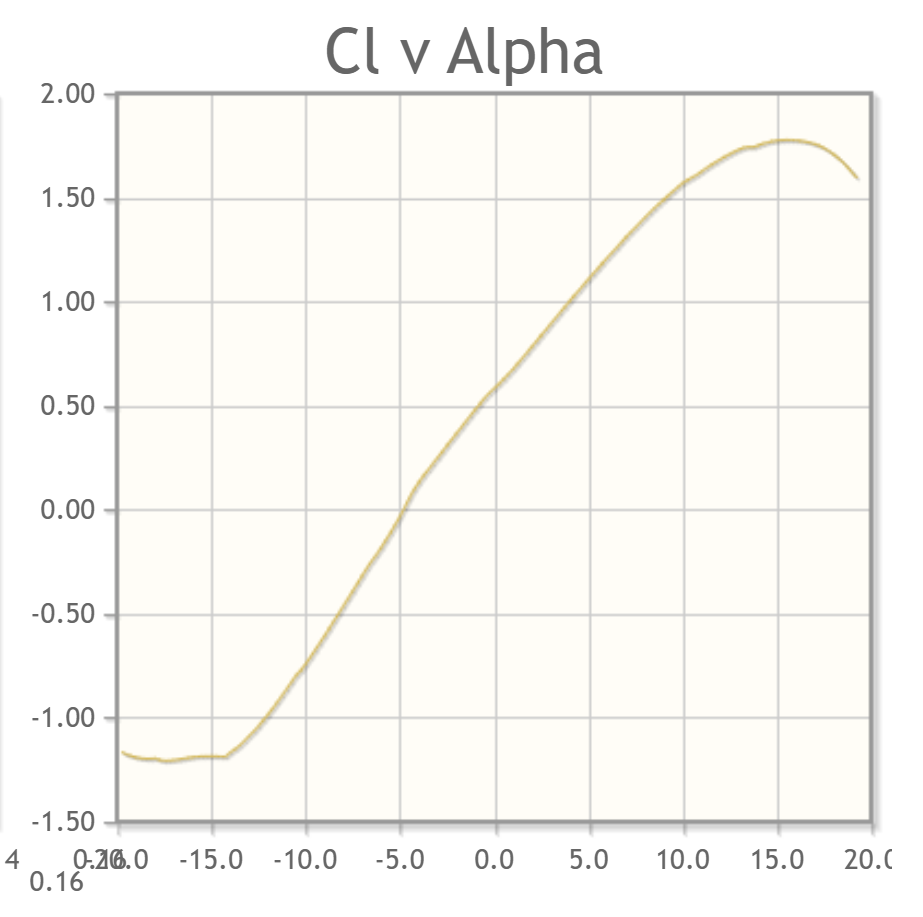

Clmin = -1.2;

Approximate 3D effects


$$C_{L_{\min } } =0\ldotp 9C_{l_{\min } } \cdot \cos \left(\Lambda_{0\ldotp 25c} \right)$$


CLmin = 0.9 .* Clmin .* cos(Sweep) 

CLmin = -0.9746


for i = 1 : length(Vspace)

    L_min(i) = 0.5 .* rho0 .* (Vspace(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmin, Vspace(i), Calt, Sweep);

end

n_lowerline = L_min ./ W0;

### **3 Limit Manoeuvring Load Factors**

**3.1 Positive Limit Manoeuvring Load Factor**

CS 25.337(b) (p.217)

$n\ge 2\ldotp 5$ and $n\ge 2\ldotp 1+\left(\frac{24000}{W+10000}\right)$

nmax = 2.1 + 24000 ./ (convmass(W0 ./ g, "kg", "lbm") + 10000)

nmax = 2.1251


if nmax >= 2.5
else
    nmax = 2.5
end

nmax = 2.5000

**3.2 Negative Limit Manoeuvring Load Factor**

CS 25.337(c) (p.217)

(i) May not be less than –1.0 at speeds up to $V_C$

(ii) Must vary linearly with speed from the value at $V_C$ to zero at $V_D$

nmin = -1;

**3.3 Positive Limit Manoeuvring Load Factor**

CS 25.345(b) (p.239)

Manoeuvring to a positive limit load factor of 2.0

nmax_L = 2.0

nmax_L = 2

**3.4 Ultimate Load Factor**

nmax_ult = nmax * 1.5

nmax_ult = 3.7500

nmin_ult = nmin * 1.5

nmin_ult = -1.5000

nmax_L_ult = nmax_L * 1.5

nmax_L_ult = 3

### **4 Design Airspeeds  (Part II)**

The selected design airspeeds are equivalent airspeeds (EAS)

**4.1 Design Stall Speed, **$V_s$


$$W=L=\frac{1}{2}\rho_0 V_S^2 S_{\textrm{ref}}$$


VS1 = Stall_Speed_Real(CLmax, Calt, W0, Sref, Sweep)          % Take-off stall speed in clean configuration (m/s)

VS1 = 93.2924


VS1_min = Stall_Speed_Real(abs(CLmin), Calt, WL, Sref, Sweep) % Take-off stall speed at minimum lift coefficient (m/s)

VS1_min = 107.6305

VS2 = Stall_Speed_Real(CLmax, Calt, WL, Sref, Sweep)          % Landing stall speed in clean configuration (m/s)

VS2 = 88.5050


VS0_L = Stall_Speed_Real(CLmaxL, Calt, WL, Sref, Sweep)       % Landing stall speed in landing configuration (m/s)

VS0_L = 62.6826


VS1_A = Stall_Speed_Real(CLmaxA, Calt, WL, Sref, Sweep)       % Landing stall speed in approach configuration (m/s)

VS1_A = 66.9948


VS1_TO = Stall_Speed_Real(CLmaxTO, Calt, W0, Sref, Sweep)     % Take-off stall speed in Take-off configuration (m/s)

VS1_TO = 75.0185

**4.2 Design Manoeuvring Speed, **$V_A$

CS 25.335 (b) (p.212)


$$V_A \ge V_{\textrm{S1}} \sqrt{n_{\max } }$$


VA = VS1 * sqrt(nmax)

VA = 147.5083

**4.3 Design Wing-flap Speed, **$V_F$

CS 25.335 (e) (p.214)

$V_F$ may not be less than 

(i) $1\ldotp 6V_{\textrm{S1}}$ with the wing-flaps in take-off position at maximum take-off weight

(ii) $1\ldotp 8V_{\textrm{S1}}$ with the wing-flaps in approach position at maximum landing weight

(iii) $1\ldotp 8V_{\textrm{S0}}$ with the wing-flaps in landing position at maximum landing weight

if 1.6 * VS1_TO >= 1.8 * VS1_A

    if 1.6 * VS1_TO >= 1.8 * VS0_L

        VF = 1.6 * VS1_TO

    else

        VF = 1.8 * VS0_L

    end

else

    if 1.8 * VS1_A >= 1.8 * VS0_L

        VF = 1.8 * VS1_A

    else

        VF = 1.8 * VS0_L

    end
end

VF = 120.5907

### **5 Manoeuver envelope**

CS 25.333 (b) (p.211)

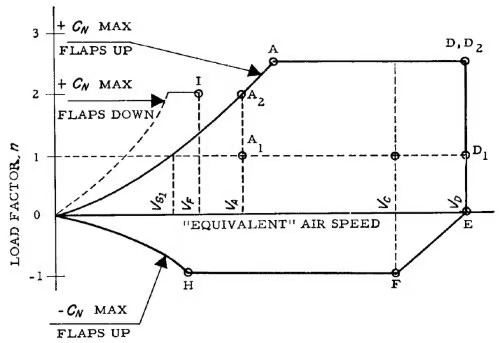

**5.1 Find intersection point of the upper curve**

Clean configuration

% 1st segment

Vspace_u1 = linspace(0, VS1, 100);

for i = 1 : length(Vspace_u1)

    L_u1(i) = 0.5 .* rho0 .* (Vspace_u1(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmax, Vspace_u1(i), Calt, Sweep);

end

n_upper1 = L_u1 ./ W0;

% 2nd segment

Vspace_u2 = linspace(VS1, VD, 100);

for i = 1 : length(Vspace_u2)

    L_u2(i) = 0.5 .* rho0 .* (Vspace_u2(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmax, Vspace_u2(i), Calt, Sweep);

end

n_upper2 = L_u2 ./ W0;

for i = 1 : length(n_upper2)

    if n_upper2(i) <= nmax 

    else

        n_upper2(i) = nmax;

    end
end

% 3rd segment

Vspace_u2 = [Vspace_u2 VD];

n_upper2 = [n_upper2 0];

Clean configuration ultimate load

% 4th segment

Vspace_u3 = linspace(VS1, VD, 100);

for i = 1 : length(Vspace_u3)

    L_u3(i) = 0.5 .* rho0 .* (Vspace_u3(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmax, Vspace_u3(i), Calt, Sweep);

end

n_upper3 = L_u3 ./ W0;

for i = 1 : length(n_upper3)

    if n_upper3(i) <= nmax_ult

    else

        n_upper3(i) = nmax_ult;

    end
end

% 5th segment

Vspace_u3 = [Vspace_u3 VD];

n_upper3 = [n_upper3 0];

Landing configuration

% 1st segment

Vspace_u1L = linspace(0, VF, 50);

for i = 1 : length(Vspace_u1L)

    L_u1L(i) = 0.5 .* rho0 .* (Vspace_u1L(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmaxL, Vspace_u1L(i), Calt, Sweep);

end

n_upperL1 = L_u1L ./ W0;

for i = 1 : length(n_upperL1)

    if n_upperL1(i) <= nmax_L

    else

        n_upperL1(i) = nmax_L;

    end
end

% 2nd segment

Vspace_u1L = [Vspace_u1L VF];

n_upperL1 = [n_upperL1 0];

Landing configuration ultimate load

% 3rd segment

Vspace_u2L = linspace(0, VF, 50);

for i = 1 : length(Vspace_u2L)

    L_u2L(i) = 0.5 .* rho0 .* (Vspace_u2L(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmaxL, Vspace_u2L(i), Calt, Sweep);

end

n_upperL2 = L_u2L ./ W0;

for i = 1 : length(n_upperL2)

    if n_upperL2(i) <= nmax_L_ult

    else

        n_upperL2(i) = nmax_L_ult;

    end
end

% 4th segment

Vspace_u2L = [Vspace_u2L VF];

n_upperL2 = [n_upperL2 0];

**5.2 Find intersection point of the lower curve**

Clean configuration

% 1st segment

Vspace_l1 = linspace(0, VS1_min, 100);

for i = 1 : length(Vspace_l1)

    L_l1(i) = 0.5 .* rho0 .* (Vspace_l1(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmin, Vspace_l1(i), Calt, Sweep);

end

n_lower1 = L_l1 ./ W0;

for i = 1 : length(n_lower1)

    if n_lower1(i) >= nmin

    else

        n_lower1(i) = nmin;

    end
end

% 2nd segment

Vspace_l2 = linspace(VS1_min, VC, 100);

for i = 1 : length(Vspace_l2)

    L_l2(i) = 0.5 .* rho0 .* (Vspace_l2(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmin, Vspace_l2(i), Calt, Sweep);

end

n_lower2 = L_l2 ./ W0;

for i = 1 : length(n_lower2)

    if n_lower2(i) >= nmin

    else

        n_lower2(i) = nmin;

    end
end

% 3rd segment

Vspace_l3 = linspace(VC, VD, 100);

n_lower3 = (1 ./ (VD - VC)) .* Vspace_l3 + (VD ./ (VC - VD));

Clean configuration ultimate load

% 5th segment

Vspace_l4 = linspace(VS1_min, VC, 100);

for i = 1 : length(Vspace_l4)

    L_l2(i) = 0.5 .* rho0 .* (Vspace_l4(i) .^ 2) .* Sref .* Comp_Effects_Real(CLmin, Vspace_l4(i), Calt, Sweep);

end

n_lower4 = L_l2 ./ W0;

for i = 1 : length(n_lower4)

    if n_lower4(i) >= nmin_ult

    else

        n_lower4(i) = nmin_ult;

    end
end

% 6th segment

Vspace_l5 = linspace(VC, VD, 100);

n_lower5 = (1.5 ./ (VD - VC)) .* Vspace_l5 + (1.5 .* VD ./ (VC - VD));

**5.3 Plot manoeuver envelope**

in m/s

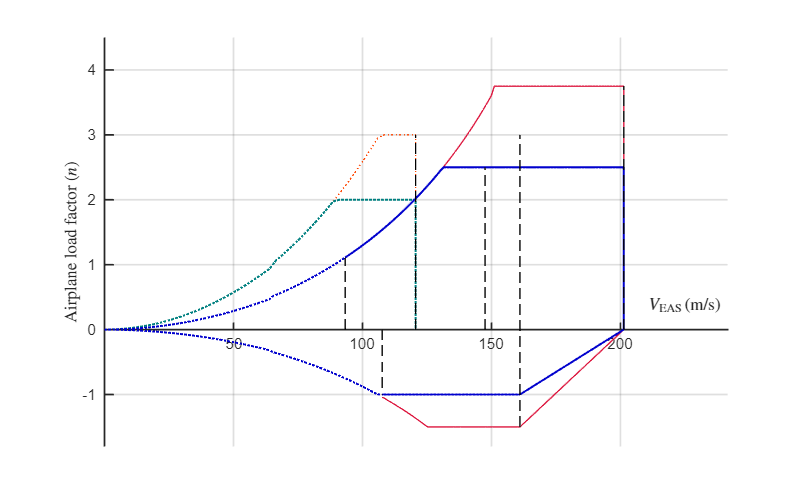

figure(1)

clf;

% Ultimate load
plot(Vspace_u2L, n_upperL2, ':', 'Color', [255/255 69/255 0/255], 'LineWidth', 1)
hold on
plot(Vspace_u3, n_upper3, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot(Vspace_l4, n_lower4, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot(Vspace_l5, n_lower5, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% Limit load
plot(Vspace_u1L, n_upperL1, ':', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5)
hold on
plot(Vspace_u1, n_upper1, ':', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_u2, n_upper2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l1, n_lower1, ':', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l2, n_lower2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l3, n_lower3, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on

% Vertical lines
plot([VS1 VS1], [0 n_upper1(end)], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold on
plot([VS1_min VS1_min], [0 n_lower1(end)], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold on
plot([VA VA], [0 nmax], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold on
plot([VC VC], [nmin_ult nmax_L_ult], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold on
plot([VD VD], [0 nmax_ult], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold on
plot([VF VF], [0 nmax_L_ult], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold off

% Axis labels with LaTeX font
xlabel('$V_{\mathrm{EAS}} \, (\mathrm{m/s})$', 'Interpreter', 'latex');
ylabel('Airplane load factor $(n)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 VD * 1.2]);
ylim([nmin_ult * 1.2 nmax_ult * 1.2]);

grid on;

% Set figure size
set(gcf, 'Position', [0 0 800 500]);

in knots

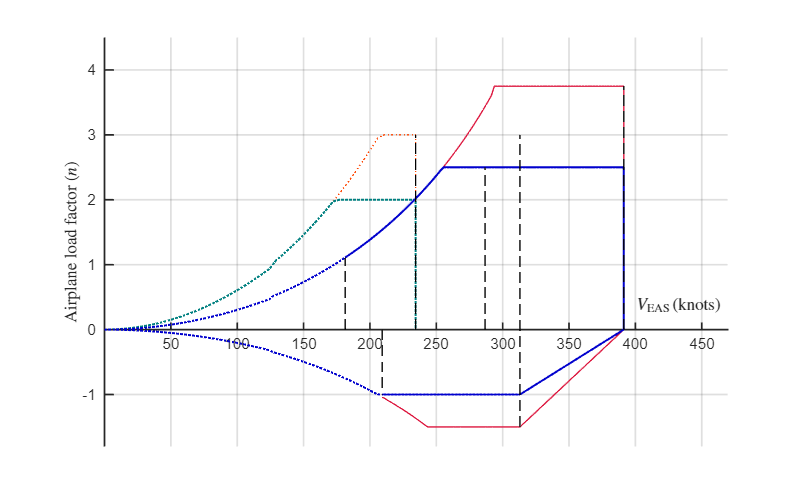

figure(2)

clf;

% Ultimate load
plot(Vspace_u2L .* 1.94384, n_upperL2, ':', 'Color', [255/255 69/255 0/255], 'LineWidth', 1)
hold on
plot(Vspace_u3 .* 1.94384, n_upper3, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot(Vspace_l4 .* 1.94384, n_lower4, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot(Vspace_l5 .* 1.94384, n_lower5, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% Limit load
plot(Vspace_u1L .* 1.94384, n_upperL1, ':', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5)
hold on
plot(Vspace_u1 .* 1.94384, n_upper1, ':', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_u2 .* 1.94384, n_upper2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l1 .* 1.94384, n_lower1, ':', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l2 .* 1.94384, n_lower2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l3 .* 1.94384, n_lower3, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on

% Vertical lines
plot([VS1 .* 1.94384 VS1 .* 1.94384], [0 n_upper1(end)], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold on
plot([VS1_min .* 1.94384 VS1_min .* 1.94384], [0 n_lower1(end)], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold on
plot([VA .* 1.94384 VA .* 1.94384], [0 nmax], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold on
plot([VC .* 1.94384 VC .* 1.94384], [nmin_ult nmax_L_ult], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold on
plot([VD .* 1.94384 VD .* 1.94384], [0 nmax_ult], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold on
plot([VF .* 1.94384 VF .* 1.94384], [0 nmax_L_ult], '--', 'Color', [0/255 0/255 0/255], 'LineWidth', 1)
hold off

% Axis labels with LaTeX font
xlabel('$V_{\mathrm{EAS}} \, (\mathrm{knots})$', 'Interpreter', 'latex');
ylabel('Airplane load factor $(n)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 VD .* 1.94384 * 1.2]);
ylim([nmin_ult * 1.2 nmax_ult * 1.2]);

grid on;

% Set figure size
set(gcf, 'Position', [0 0 800 500]);

### **6 Gust envelope**

CS 25.341 (a) (p.219)

Airframe Structural Design (p.43)

**Discrete gust criteria are used for simplicity, regulatory compliance,  and to analyze worst-case gust loads efficiently, ensuring structural  integrity without the complexity of continuous turbulence models.**

The concept pictures the airplane flying along at a constant velocity, $V$, and suddenly encountering a sharped-edged gust.

The gust velocity $U_{\textrm{de}}$ is assumed to act vertically, normal to the flight path and is of uniform intensity across the wing span.

**6.1 Design Speed for maximum gust intensity**

CS 25.335 (d) (p.213)

$V_B \ge V_{\textrm{S1}} {\left\lbrack 1+\frac{K_g U_{\textrm{ref}} V_C a}{498w}\right\rbrack }^{\frac{1}{2}}$ in knots

basic parameters

VS1_g = VS1 * 1.94384      % Take-off stall speed in clean configuration (knots)

VS1_g = 181.3455


CNAmax = CLmax             % Maximum aeroplane normal force coefficient in cruise

CNAmax = 1.4413


VC_g = VC * 1.94384        % Design equivalent cruise speed (knots)

VC_g = 313.0014


VD_g = VD * 1.94384        % Design equivalent dive speed (knots)

VD_g = 391.2517


rho_g = rhoC               % Air density at the cruise altitude (kg/m^3)

rho_g = 0.4931

rho_g = 0.00194032 * rho_g % Air density at the cruise altitude (slugs/ft^3)

rho_g = 9.5671e-04


c_g = c * 3.280839895      % Mean geometric chord of the wing (ft)

c_g = 27.6953


g_g = g * 3.28084          % Standard acceleration of gravity (ft/s^2)

g_g = 32.1740


w = W0 ./ Sref             % Average wing loading (N/m^2)

w = 7.6834e+03

w = w .* 0.020885434       % Average wing loading (lb/ft^2)

w = 160.4710

find mass ratio, $\mu$

miu = (2 .* w) ./ (rho_g * c_g * a * g_g)

miu = 84.8693

find gust alleviation factor, $K_g$ 

K_g = 0.88 .* miu ./ (5.3 + miu)

K_g = 0.8283

find reference gust velocities $U_{\textrm{ref}} \;$by linearly interpolation

(i) at aeroplane speeds between $V_B$ and $V_C$

$U_{\textrm{ref}} =U_{\textrm{ref20}} -\frac{\left(h-20000\right)}{\left(50000-20000\right)}\left(U_{\textrm{ref20}} -U_{\textrm{ref50}} \right)$ in ft/s

% U_refB = 44 - ((C_alt - 20000) ./ (50000 - 20000)) .* (44 - 26)
% U_refC = 44 - ((C_alt - 20000) ./ (50000 - 20000)) .* (44 - 26)

read from Airframe Structural Design (p.44)

U_refB = 58.53;
U_refC = 43.33;

(ii) at aeroplane design speed between $V_D$

% U_refD = 0.5 * U_ref1
U_refD = 21.67;

Therefore

VB = VS1_g .* (1 + (K_g .* U_refB .* VC_g .* a) ./ (498 .* w)) .^ 0.5

VB = 246.1412

VB_ms = VB ./ 1.94384

VB_ms = 126.6263

**6.2 Gust load factor**

Calculate the change in load factor due to gust


$$\Delta n=K_g \frac{U_e \textrm{Va}}{498w}$$


n_VB = K_g * U_refB * VB * a ./ (498 * w)

n_VB = 0.6624

n_VC = K_g * U_refC * VC_g * a ./ (498 * w)

n_VC = 0.6235

n_VD = K_g * U_refD * VD_g * a ./ (498 * w)

n_VD = 0.3898

**5.3 Plot V-n diagram**

in m/s

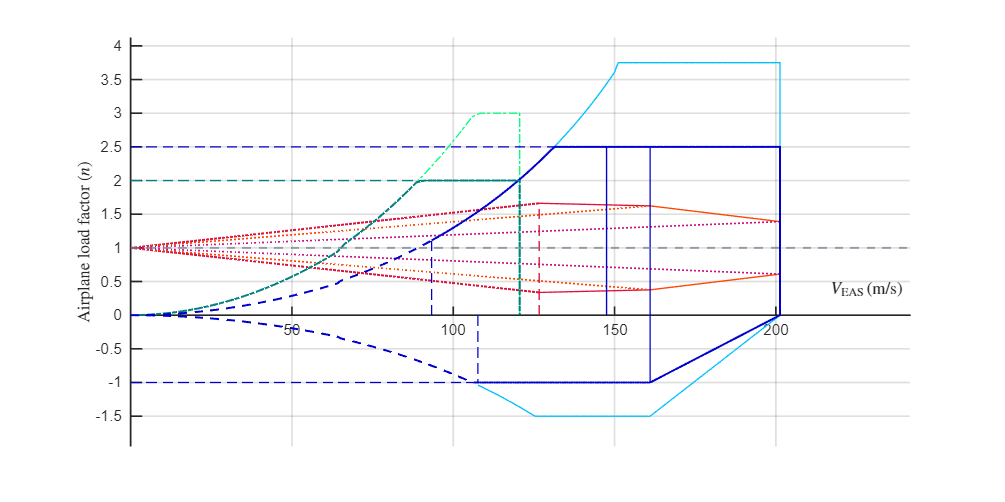

figure(3)

clf;

% Gust
plot([0 VB_ms], [1 1 + n_VB], ':', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5)
hold on
plot([0 VB_ms], [1 1 - n_VB], ':', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5)
hold on
plot([VB_ms VC], [1 + n_VB 1 + n_VC], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot([VB_ms VC], [1 - n_VB 1 - n_VC], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot([0 VC], [1 1 + n_VC], ':', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.25)
hold on
plot([0 VC], [1 1 - n_VC], ':', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.25)
hold on
plot([VC VD], [1 + n_VC 1 + n_VD], '-', 'Color', [255/255 69/255 0/255], 'LineWidth', 1)
hold on
plot([VC VD], [1 - n_VC 1 - n_VD], '-', 'Color', [255/255 69/255 0/255], 'LineWidth', 1)
hold on
plot([0 VD], [1 1 + n_VD], ':', 'Color', [199/255 21/255 133/255], 'LineWidth', 1.25)
hold on
plot([0 VD], [1 1 - n_VD], ':', 'Color', [199/255 21/255 133/255], 'LineWidth', 1.25)
hold on

% Ultimate load
plot(Vspace_u2L, n_upperL2, '-.', 'Color', [0/255 255/255 127/255], 'LineWidth', 1)
hold on
plot(Vspace_u3, n_upper3, '-', 'Color', [0/255 191/255 255/255], 'LineWidth', 1)
hold on
plot(Vspace_l4, n_lower4, '-', 'Color', [0/255 191/255 255/255], 'LineWidth', 1)
hold on
plot(Vspace_l5, n_lower5, '-', 'Color', [0/255 191/255 255/255], 'LineWidth', 1)
hold on

% Limit load
plot(Vspace_u1L, n_upperL1, '-.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5)
hold on
plot(Vspace_u1, n_upper1, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_u2, n_upper2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l1, n_lower1, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l2, n_lower2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l3, n_lower3, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on

% Vertical lines
plot([VS1 VS1], [0 n_upper1(end)], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot([VS1_min VS1_min], [0 n_lower1(end)], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot([VA VA], [0 nmax], '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot([VB_ms VB_ms], [0 1 + n_VB], '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot([VC VC], [nmin nmax], '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on

% Limits
yline(1,'--', 'Color', [112/255 128/255 144/255], 'LineWidth', 1.5)
plot([0 VA], [nmax nmax], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot([0 VA], [nmin nmin], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot([0 VF], [nmax_L nmax_L], '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold off

% Axis labels with LaTeX font
xlabel('$V_{\mathrm{EAS}} \, (\mathrm{m/s})$', 'Interpreter', 'latex');
ylabel('Airplane load factor $(n)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 VD * 1.2]);
ylim([nmin_ult * 1.3 nmax_ult * 1.1]);

yticks(nmin_ult-1:0.5:nmax_ult+1)

grid on;

% Set figure size
set(gcf, 'Position', [0 0 1000 500]);

in knots

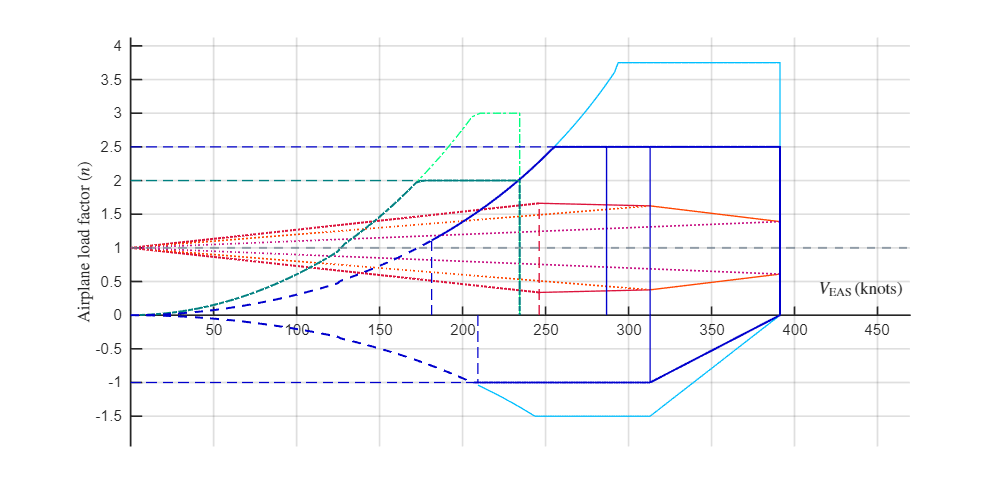

figure(4)

clf;

% Gust
plot([0 VB], [1 1 + n_VB], ':', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5)
hold on
plot([0 VB], [1 1 - n_VB], ':', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5)
hold on
plot([VB VC_g], [1 + n_VB 1 + n_VC], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot([VB VC_g], [1 - n_VB 1 - n_VC], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot([0 VC_g], [1 1 + n_VC], ':', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.25)
hold on
plot([0 VC_g], [1 1 - n_VC], ':', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.25)
hold on
plot([VC_g VD_g], [1 + n_VC 1 + n_VD], '-', 'Color', [255/255 69/255 0/255], 'LineWidth', 1)
hold on
plot([VC_g VD_g], [1 - n_VC 1 - n_VD], '-', 'Color', [255/255 69/255 0/255], 'LineWidth', 1)
hold on
plot([0 VD_g], [1 1 + n_VD], ':', 'Color', [199/255 21/255 133/255], 'LineWidth', 1.25)
hold on
plot([0 VD_g], [1 1 - n_VD], ':', 'Color', [199/255 21/255 133/255], 'LineWidth', 1.25)
hold on


% Ultimate load
plot(Vspace_u2L .* 1.94384, n_upperL2, '-.', 'Color', [0/255 255/255 127/255], 'LineWidth', 1)
hold on
plot(Vspace_u3 .* 1.94384, n_upper3, '-', 'Color', [0/255 191/255 255/255], 'LineWidth', 1)
hold on
plot(Vspace_l4 .* 1.94384, n_lower4, '-', 'Color', [0/255 191/255 255/255], 'LineWidth', 1)
hold on
plot(Vspace_l5 .* 1.94384, n_lower5, '-', 'Color', [0/255 191/255 255/255], 'LineWidth', 1)
hold on

% Limit load
plot(Vspace_u1L .* 1.94384, n_upperL1, '-.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5)
hold on
plot(Vspace_u1 .* 1.94384, n_upper1, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_u2 .* 1.94384, n_upper2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l1 .* 1.94384, n_lower1, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l2 .* 1.94384, n_lower2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on
plot(Vspace_l3 .* 1.94384, n_lower3, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on

% Vertical lines
plot([VS1 .* 1.94384 VS1 .* 1.94384], [0 n_upper1(end)], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot([VS1_min .* 1.94384 VS1_min .* 1.94384], [0 n_lower1(end)], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot([VA .* 1.94384 VA .* 1.94384], [0 nmax], '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot([VB_ms .* 1.94384 VB_ms .* 1.94384], [0 1 + n_VB], '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot([VC .* 1.94384 VC .* 1.94384], [nmin nmax], '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on

% Limits
yline(1,'--', 'Color', [112/255 128/255 144/255], 'LineWidth', 1.5)
plot([0 VA .* 1.94384], [nmax nmax], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot([0 VA .* 1.94384], [nmin nmin], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot([0 VF .* 1.94384], [nmax_L nmax_L], '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold off

% Axis labels with LaTeX font
xlabel('$V_{\mathrm{EAS}} \, (\mathrm{knots})$', 'Interpreter', 'latex');
ylabel('Airplane load factor $(n)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 VD_g * 1.2]);
ylim([nmin_ult * 1.3 nmax_ult * 1.1]);

yticks(nmin_ult-1:0.5:nmax_ult+1)

grid on;

% Set figure size
set(gcf, 'Position', [0 0 1000 500]);